Here are the error message returned by each reader:
Undefined function 'wavread' for input arguments of type 'char'.
Undefined function 'auread' for input arguments of type 'char'.
Error using mp3read>mysystem (line 315)
unable to execute mp3info -r m -p "%Q %u %b %r %v * %C %e %E %L %O %o %p" ragtime.wav (/bin/bash: mp3info: command not found
)
Error using aiffread (line 127)
Unknown file extension '.wav'.


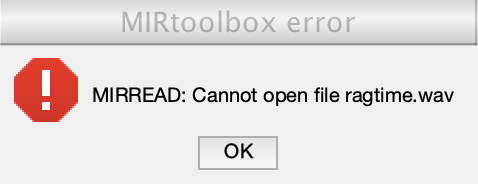

Error using mirerror (line 4)
ERROR using MIRREAD: Cannot open file ragtime.wav

Error in mirread2014>misread (line 200)
mirerror('MIRREAD',['Cannot open file ',file]);

Error in 

%% Basics

% This is a demo live script. Just remember to change the folder in matlab
% to where you downloaded the MIRtoolbox_tutorial1 materials.
clc; clf
mirverbose(0); % less cluttered display
a = miraudio('ragtime.wav') % this is a comment

mirplay(a);


## Simple edits

clf % clear figure
a2=miraudio('ragtime.wav','Extract',2.2,2.6)
mirplay(a2)

## Spectrum

clf; p=mirpeaks(mirspectrum(a2,'Max',2500),'Total',3)
mirgetdata(p)
%s=mirspectrum(a, 'Frame', 'Max', 2500,'dB')


mirplayer(s)



## Different options


b = mirbrightness('InTheMood.mp3', 'Frame')
r = mirroughness('InTheMood.mp3')
